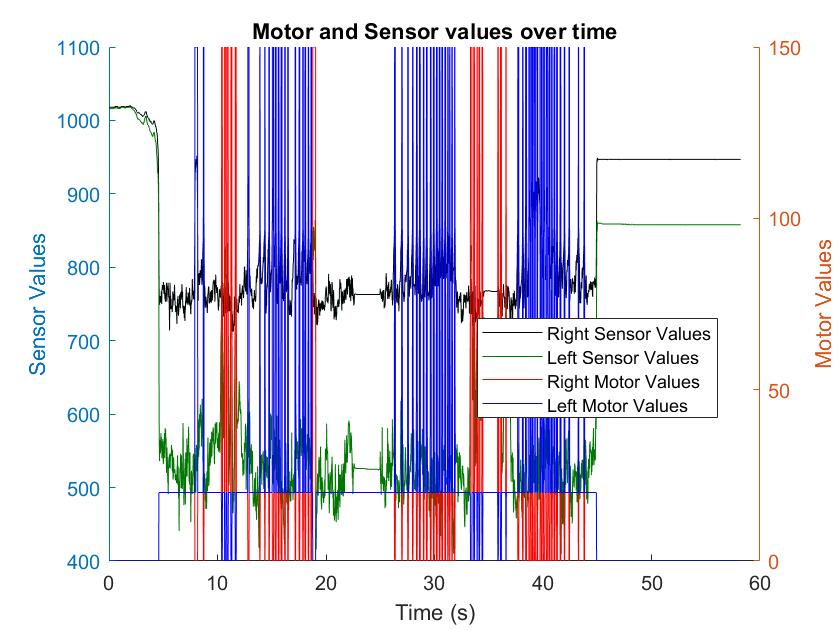

data = csvread("serial_data.csv");

t = linspace(0, 58.22, 2912);
right_sensor = data(:, 1);
left_sensor = data(:, 2);
right_wheel = data(:, 3);
left_wheel = data(:, 4);

clf
title("Motor and Sensor values over time")
xlabel("Time (s)")
hold on
yyaxis left
ylabel("Sensor Values")
plot(t, right_sensor, 'Color', '#000707', "LineStyle", '-')
plot(t, left_sensor, 'Color', '#007700', "LineStyle", '-')

yyaxis right
ylabel("Motor Values")
plot(t, right_wheel, 'Color', '#ff0000', "LineStyle", '-')
plot(t, left_wheel, 'Color', '#0000ff', "LineStyle", '-')

legend("Right Sensor Values", "Left Sensor Values", "Right Motor Values", "Left Motor Values", "Location","best")
hold off